# Homework 2: Restricted Boltzmann machine

The goal of this exercise is to train a restricted Boltzmann machine to learn the XOR data set.

In the XOR data set, the three-bit patterns shown in the Figure to the right are assigned probability $\frac{1}{4}$, all other patterns are assigned probability zero. Here □ corresponds to -1, and ■ to +1. See Figure 4.5 in the lecture notes.

Train a restricted Boltzmann machine with three visible and *M*=1,2,4,8 hidden neurons (all +/-1 neurons) using the CD-k algorithm. Experiment with different values for *k* and for the learning rate *η*. Make sure that you use the correct algorithm for +/-1 neurons (Algorithm 3 in the course book).

Compute the Kullback-Leibler divergence as a function of the number of hidden neurons: iterate the dynamics of the restricted Boltzmann machine after training, and count the frequencies at which the different patterns occur. Determine for how long you must run the dynamics to get a precise estimate of the probabilities. Plot the Kullback-Leibler divergence vs. M. Also plot the theory [Equation (4.40)], compare, and discuss your results.

## Parameters

clc
clear
x1 = [-1;-1;-1];
x2 = [1;-1;1];
x3 = [-1;1;1];
x4 = [1;1;-1];
x = [x1,x2,x3,x4];
x5 = [-1;-1;1];
x6 = [1;-1;-1];
x7 = [-1;1;-1];
x8 =[1;1;1];
x_all = [x1,x2,x3,x4,x5,x6,x7,x8];
P_data = 1/4;
counter = 5;
trials = 1000;
minibatch_n = 20;
k = 500;
Nout = 3000;
Nin = 2000;
NN = Nout*Nin;
% M = 4;
M_list = [1,2,3,4,8];
N = 3;
% V = zeros([N,1]);
% H = zeros([M,1]);
% w = normrnd(0, 1/sqrt(N), [M,N]);
% theta_v = zeros([N,1]);
% theta_h = zeros([M,1]);
eta = 0.003;%3
D_KL_list=[];


for iter = 1:length(M_list)  % loop through M=1,2,3,4,8
    M = M_list(iter); 
    D_KL_minimal = 5;
    for count = 1:counter % convergence over D_KL
        V = zeros([N,1]);
        H = zeros([M,1]);
        w = normrnd(0, 1/sqrt(N), [M,N]);
        theta_v = zeros([N,1]);
        theta_h = zeros([M,1]);
        for trial = 1:trials % convergence over w theta_v theta_h
            delta_w = zeros([M,N]);
            delta_theta_v = zeros([N,1]);
            delta_theta_h = zeros([M,1]);
        %     input_batch = [x(:,randi(4)),x(:,randi(4)),x(:,randi(4))]; % sample 3 patterns from the data distribution
            for p = 1:minibatch_n % feed all the patterns in the minibatch
                input_pattern = x_all(:,randi(4)); % [3x1]
                V_0 = input_pattern;
                V = input_pattern;
                b_h_0 = w*V_0 - theta_h;
                % update Hidden neurons
                b_h = w*V - theta_h; % [Mx1]        
                for idx = 1:M
                    r = rand(1);
                    if r < P_Boltz(b_h(idx))
                        H(idx) = 1;
                    else
                        H(idx) = -1;
                    end
                end
        
                % loop over CD-k
                for t = 1:k
                    % update all visible neurons
                    b_v = w' * H - theta_v; % [3x1]
                    for idx = 1:N
                        r = rand(1);
                        if r < P_Boltz(b_v(idx))
                            V(idx) = 1;
                        else
                            V(idx) = -1;
                        end
                    end
                    % update all hidden neurons
                    b_h = w*V - theta_h; % [Mx1]        
                    for idx = 1:M
                        r = rand(1);
                        if r < P_Boltz(b_h(idx))
                            H(idx) = 1;
                        else
                            H(idx) = -1;
                        end
                    end
                end % end of loop over k times
                
                % compute weight and threshold increments delta_w_mn
                for m = 1:M %1->M
        %             bm_h_0 = w(m,:)*V_0 - theta_h(m);
                    bm_h_k = w(m,:)*V - theta_h(m); 
                    for n = 1:length(V) % 1->3           
                        delta_w(m,n) =  delta_w(m,n) + eta * (tanh(b_h_0(m))*V_0(n)-tanh(bm_h_k)*V(n)); % why +=?
        %                 delta_theta_v(n) = delta_theta_v(n) - eta * (V_0(n)-V(n));               
                    end
                    delta_theta_h(m) = delta_theta_h(m) - eta * (tanh(b_h_0(m)) - tanh(bm_h_k));
                end % end of calculate delta's
                delta_theta_v = delta_theta_v - eta * (V_0-V);
            end % end of minibatches
            
            % update weights and threshold
            w = w + delta_w;
            theta_v = theta_v + delta_theta_v;
            theta_h = theta_h + delta_theta_h;
        end % end of trials, trainings
    
        % Kullback-Leibler divergence.
        P_B = zeros([1,8]);
        % start the outer loop
        for l = 1:Nout
            p_selected = x_all(:,randi(8));
            V = p_selected;
        
            % update Hidden neurons
            b_h = w*V - theta_h; % [Mx1]        
            for idx = 1:M
                r = rand(1);
                if r < P_Boltz(b_h(idx))
                    H(idx) = 1;
                else
                    H(idx) = -1;
                end
            end
        
            % start the inner loop
            for t = 1:Nin
                % update all visible neurons
                b_v = w' * H - theta_v; % [3x1]
                for idx = 1:N
                    r = rand(1);
                    if r < P_Boltz(b_v(idx))
                        V(idx) = 1;
                    else
                        V(idx) = -1;
                    end
                end
                % update all hidden neurons
                b_h = w*V - theta_h; % [Mx1]        
                for idx = 1:M
                    r = rand(1);
                    if r < P_Boltz(b_h(idx))
                        H(idx) = 1;
                    else
                        H(idx) = -1;
                    end
                end
                
                % check which pattern of dataset is V
                for idx = 1:8
                    if isequal(x_all(:,idx), V)
                        P_B(idx) = P_B(idx) + 1;
                    end
                end
            end % end of inner loop
        end % end of outer loop
        P_B = P_B/NN;
        D_KL = 0;
        for idx = 1:4
            D_KL = D_KL + P_data * log(P_data/P_B(idx));
        end
        if D_KL < D_KL_minimal
            D_KL_minimal = D_KL;
        end
    end
    D_KL_list(end+1) = D_KL_minimal;
end

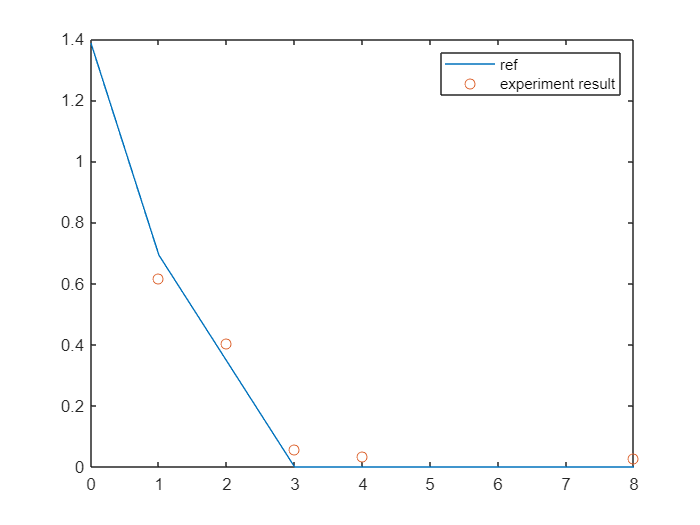

D_KL_Blist = [];
M_list_rf =[0,1,2,3,4,8];
for iter = 1:length(M_list_rf)
    M = M_list_rf(iter);
    if M < 2^(N-1)-1
        D_KL_bound = log(2)*(N-fix(log2(M+1))-(M+1)/(2^fix((log2(M+1)))));
%         D_KL_bound = N-fix(log2(M+1))-(M+1)/(2^fix((log2(M+1))));
    else
        D_KL_bound = 0;
    end
    D_KL_Blist(end+1) = D_KL_bound;
end
figure
plot(M_list_rf,D_KL_Blist)
hold on
scatter(M_list, D_KL_list)
legend("ref","experiment result")

function p = P_Boltz(b)
    p = 1/(1+exp(-2*b));
end